fstart = 1e9;
fend = 6e9;
bscan = zeros(11, 501);

for nY = -5:1:5
    s21_data = readmatrix("./s21_results/setup_2_bscan/s21_bscan_ny_" + ...
                        string(nY) + ".csv");
    amplitude = s21_data(:, 2);
    phase = s21_data(:, 3);
    [st, dr] = calc_range(fstart, fend, amplitude, phase);
    bscan(nY + 6, :) = abs(st);
end

img = bscan(:, 1:50);
img = 10 * log10(img);
img = img';

x = -5:1:5;
y = [(0:49)*dr];

figure
imagesc(x, y, -img)
colormap gray
colorbar
xlabel('Distance - Y axis (10m)');
ylabel('Distance - X axis (m)');

interpolated_img = zeros(50, 40);
for i = 1:50
    for j = 1:10
        a = img(i, j);
        b = img(i, j+1);
        interpolated_img(i, (j-1)*4 + 1) = a;
        interpolated_img(i, (j-1)*4 + 2) = (3*a+b) / 4;
        interpolated_img(i, (j-1)*4 + 3) = (a+b) / 2;
        interpolated_img(i, (j-1)*4 + 4) = (a+3*b) / 4;
    end
end

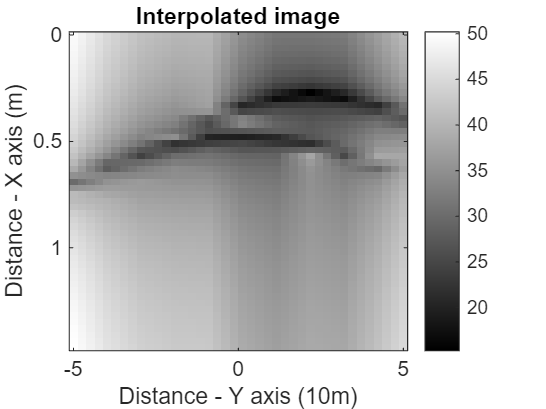

figure
imagesc(x, y, -interpolated_img)
colormap gray
colorbar
title('Interpolated image');
xlabel('Distance - Y axis (10m)');
ylabel('Distance - X axis (m)');